# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

# Tema 5: - Clasificador de Dígitos Usando HOG Features

Este ejemplo muestra cómo clasificar dígitos utilizando características HOG y un clasificador SVM multiclase.

La clasificación de objetos es una tarea importante en muchas aplicaciones de visión por ordenador, incluyendo la vigilancia, la seguridad en el automóvil y la recuperación de imágenes. Independientemente del tipo de objeto que se clasifique, el procedimiento básico para crear un clasificador de objetos es el siguiente

- Adquirir un conjunto de datos etiquetados con imágenes del objeto deseado.

- Dividir el conjunto de datos en un conjunto de entrenamiento y un conjunto de test.

- Entrenar el clasificador utilizando las características extraídas del conjunto de entrenamiento.

- Probar el clasificador utilizando las características extraídas del conjunto de test.

El **objetivo** de este ejercicio es  clasificar dígitos numéricos utilizando características `HOG` (`Histogram of Oriented Gradient`) y un clasificador multiclase `SVM` (`Support Vector Machine`). Este tipo de clasificación se utiliza a menudo en muchas aplicaciones de reconocimiento óptico de caracteres (`OCR`).

**Nota**: El ejemplo utiliza la función `fitcecoc` de la `Statistics and Machine Learning Toolbox™` y la función `extractHOGFeatures` de la `Computer Vision Toolbox™`. (Estas toolbox deberían estar instaladas)

close all;
clear all; 
clc; 
addpath(genpath(pwd));

## (Etapa 1) Base de datos.

Se va a utilizar un conjunto de imágenes de dígitos sintéticos de 16x16 píxeles, que están contenidos en `digits.zip,` (también se puede obtener de `Computer Vision Toolbox™`). 

El conjunto de **entrenamiento** consta de 101 imágenes para cada uno de los 10 dígitos (**1010** imágenes). Cada una de las imágenes de entrenamiento contiene un dígito rodeado de otros dígitos, lo que imita cómo se ven normalmente los dígitos juntos. 

Aunque no es el conjunto de datos más representativo, hay suficientes datos para entrenar y probar un clasificador, y mostrar la viabilidad del enfoque.

**Se Pide:**

- Muestre 3 imágenes del conjunto de entrenamiento tomadas de forma aleatoria (puede utilizar la función [randi](https://es.mathworks.com/help/matlab/ref/double.randi.html) para obtener número enteros de forma aleatoria).

% Datos para TRAIN
% (opción a) a partir de Computer Vision Toolbox™
% trainingSet_path = fullfile(toolboxdir('vision'),'visiondata','digits','synthetic');
% (opción b) a partir del fichero digits.zip
trainingSet_path = 'digits/synthetic/';

trainingSet = imageDatastore(trainingSet_path,'IncludeSubfolders',true,'LabelSource','foldernames');
countEachLabel(trainingSet)

ans = 10×2 table
    Label    Count
    _____    _____

      0       101 
      1       101 
      2       101 
      3       101 
      4       101 
      5       101 
      6       101 
      7       101 
      8       101 
      9       101 


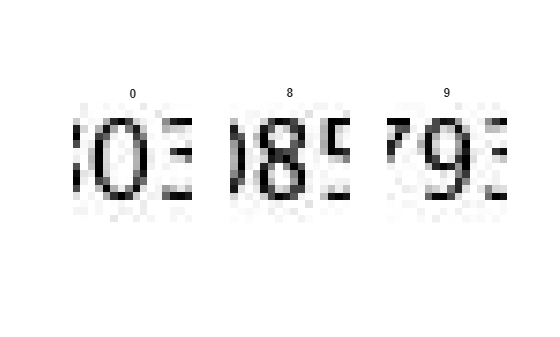


% COMPLETE el codigo para:
% mostrar 3 imágenes de entrenamiento tomadas de forma aleatoria
figure;
for i=1:3
    subplot(1,3,i);
 
    
    % 1. Generamos un índice aleatorio entre 1 y el número total de archivos
    idx = randi(numel(trainingSet.Files));
    
    % 2. Leemos la imagen correspondiente a ese índice usando readimage
    img = readimage(trainingSet, idx);
    
    % 3. Mostramos la imagen
    imshow(img);
    
    % 4. Ponemos la etiqueta del dígito como título
    title(char(trainingSet.Labels(idx)));
end

## (Etapa 2) **Extracción de características**.

Los datos utilizados para entrenar el clasificador son vectores de características HOG extraídos de las imágenes de entrenamiento y que se pueden obtener con la función [`extractHOGFeatures`](https://es.mathworks.com/help/vision/ref/extracthogfeatures.html?searchHighlight=extractHOGFeatures&s_tid=srchtitle_support_results_1_extractHOGFeatures). 

La función [`extractHOGFeatures`](https://es.mathworks.com/help/vision/ref/extracthogfeatures.html?searchHighlight=extractHOGFeatures&s_tid=srchtitle_support_results_1_extractHOGFeatures) puede devolver el resultado de visualización. Variando el parámetro del tamaño de la celda HOG (CellSize`)` y visualizando el resultado, se puede ver el efecto que tiene el parámetro del tamaño de la celda en la cantidad de información codificada en el vector de características.

**Se pide:**

- Uno de los parámetros que hay que cambiar es el tamaño de celda (`CellSize``)`, por defecto es `[8 8]`, dado que las imágenes son de 16x16 píxeles este tamaño codifica insuficiente información, por lo que debe cambiar el tamaño a [4 4] y luego a [2 2], visualizar en ambos casos el resultado para la imagen 1 y elijir uno de los dos valores utilizados para continuar con la práctica.

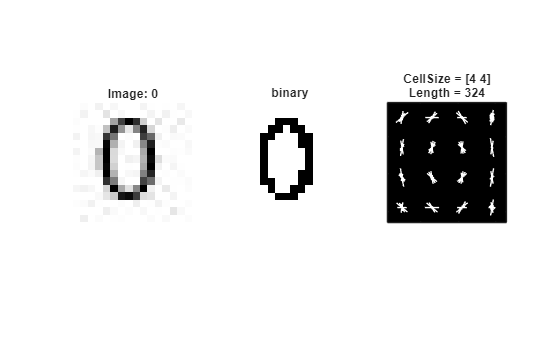

% (a) Cálculo del tamaño del vector de características de HOG

% se lee la primera imagen del dataset de train
image_num = 1;
img = readimage(trainingSet,image_num);

% tamaño de la celda HOG 
CellSize = [4 4]; % RELLENAR AQUí!!!

% valores por defecto de extractHOGFeatures
BlockSize = [2 2];
BlockOverlap = ceil(BlockSize/2);
NumBins = 9;
% Cálculo automático de cuántos bloques caben
BlocksPerImage = floor((size(img(:,:,1))./CellSize - BlockSize)./(BlockSize - BlockOverlap) + 1);
% tamaño del vector de características de HOG
hogFeatureSize = prod([BlocksPerImage, BlockSize, NumBins]);

% extracción del vector de caracterísitcas de HOG
[hog_vect, hog_vis] = extractHOGFeatures(img,'CellSize',CellSize);

% visualización del vector de caracterísitcas de HOG
figure; 
subplot(1,3,1);
imshow(img);
title(['Image: ' char(trainingSet.Labels(image_num))]);
grey = im2gray(img);
% Apply pre-processing steps
bw = imbinarize(grey);
subplot(1,3,2);
imshow(bw);
title('binary')
% Visualize the HOG features
subplot(1,3,3);  
plot(hog_vis); 
title(sprintf('CellSize = [%d %d]\nLength = %d',CellSize(1,1),CellSize(1,2),hogFeatureSize));

**Se pide:**

- Complete el bucle que extrae las características HOG de cada imagen del conjunto de entranmiento con la función [`extractHOGFeatures`](https://es.mathworks.com/help/vision/ref/extracthogfeatures.html?searchHighlight=extractHOGFeatures&s_tid=srchtitle_support_results_1_extractHOGFeatures), asegurándose de que utilice el tamaño de celda `CellSize`, y guarde los vectores en la variable llamada `trainingFeatures`. 

% (b) Extracción de caracterísitcas para el conjunto de datos de TRAIN

% Se calcula el número de elementos de la matriz con 'numel'
numImagesTrain = numel(trainingSet.Files);
trainingFeatures = zeros(numImagesTrain,hogFeatureSize,'single');

for i = 1:numImagesTrain
    % se lee cada imagen
   img = readimage(trainingSet, i); % COMPLETAR AQUÍ!!!!
    % se extrae el descriptor HOG y se guarda
    trainingFeatures(i, :) = extractHOGFeatures(img, 'CellSize', CellSize);  % COMPLETAR AQUÍ!!!!  
end

% se obtienen las etiquetas para cada imagen.
trainingLabels = trainingSet.Labels;


## (Etapa 3) Entrenamiento

El entrenamiento del clasificador de dígitos se realiza con la función [fitcecoc](https://www.mathworks.com/help/stats/fitcecoc.html), que ajustar modelos multiclase para máquinas de vectores soporte (SVM) u otros clasificadores. Los datos para entrenar son las características HOG extraídas del conjunto de entrenamiento. Se puede configurar el esquema de codificación multiclase como `'one-vs-one' `ó `'one-vs-all'`.

**Se pide:**

- Rellene la función [fitcecoc](https://www.mathworks.com/help/stats/fitcecoc.html) para que realice el entrenamiento, utilizando una codificación ('`Coding'`) 'One-vs-One' para crear el clasificador multiclase utilizando SVMs binarias. El modelo del clasificador se guardará en la variable llamada **MdlClassifier**`.`

**Nota**: para utilizar la función [`fitcecoc`](https://es.mathworks.com/help/stats/fitcecoc.html?searchHighlight=fitcecoc&s_tid=srchtitle_support_results_1_fitcecoc) hay que tener instlada la Toolbox™ `Statistics and Machine Learning`.

% fitcecoc uses SVM learners and a 'One-vs-One' encoding scheme.
MdlClassifier = fitcecoc(trainingFeatures, trainingLabels, 'Coding', 'onevsone'); %completar

## (Etapa 4) Predicción

Se obtienen las predicciones del modelo entrenado para todas las imágenes de test con la función [predict](https://es.mathworks.com/help/stats/classificationecoc.predict.html).

El conjunto de **test** consta de 12 imágenes por dígito (**120** imágenes). Para las pruebas, se utilizan escaneos de dígitos escritos a mano para validar el rendimiento del clasificador con datos diferentes a los de entrenamiento. 

**Se pide:**

- Cargue el conjunto de datos de **test **(`'digits/handwritten/'`), al igual que ha realizado en la etapa 1.

- Extraiga las características HOG para este conjunto de datos, del mismo modo se ha realizado en la etapa 2 (¡OJO! debe tener el mismo tamaño de celda **CellSize**, por lo que debe haber ejecutado previamente la Etapa 2).

- Por último, obtenga las predicciones para cada una de las imagenes de test con la función [predict](https://es.mathworks.com/help/stats/classificationecoc.predict.html) y guardelas en la variable llamada `predictedLabels`.

% Datos para TEST
testSet = imageDatastore('digits/handwritten/', 'IncludeSubfolders', true, 'LabelSource', 'foldernames');


numImagesTest = numel(testSet.Files);
testFeatures = zeros(numImagesTest, hogFeatureSize, 'single');
for i = 1:numImagesTest
    testFeatures(i, :) = extractHOGFeatures(readimage(testSet, i), 'CellSize', CellSize);
end
% -----------------------------------------------------------------------------

% Predicciones de clase utilizando las características HOG de las imagenes de test.
predictedLabels = predict(MdlClassifier, testFeatures);

## (Etapa 5) Resultados

Se debe evaluar el clasificador utilizando los resultados obtenidos para el conjunto de test, generando la matriz de confusión y calculando a partir de ésta  parámetros como: `Accuracy, Macro_Recall, Macro_Precision y Macro_F1_score`.

**Se pide:**

- Calcule la matriz de confusión con la función [confusionmat](https://es.mathworks.com/help/stats/confusionmat.html) o [confusionchart](https://es.mathworks.com/help/releases/R2025a/deeplearning/ref/confusionchart.html) y guarde el resultado en una variable llamada `CM`. 

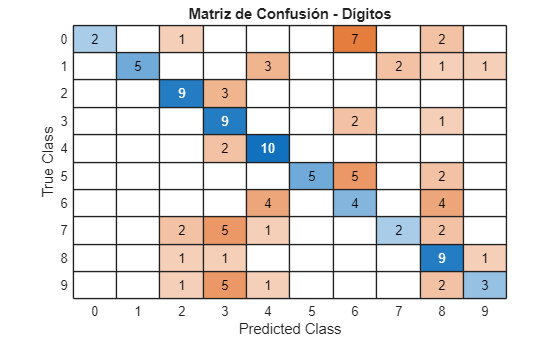

% Matriz de Confusión
% Compara las etiquetas reales (testSet.Labels) con las predichas (predictedLabels)
CM = confusionmat(testSet.Labels, predictedLabels); 

% Opcional: Para visualizarla gráficamente como pide el enunciado ("o confusionchart")
figure;
confusionchart(testSet.Labels, predictedLabels);
title('Matriz de Confusión - Dígitos');

**Se pide:**

- Codifique una función llamada `multiclass_scores` a la que se le pase la matriz de confusión `CM` y devuelva dos arrays: el primero llamado `ClassScores` de tamaño *Mx3*, donde *M* es el número filas que se corresponde con el número de clase (en este caso 10 clases, una para cada dígito) y tres columnas en las que está el cálculo de: `Recall, Precision` y `F1_Score` para cada una de las clases. El segundo array llamado MacroScores es de tamaño 1x3 y contiene los siguientes valores:` Macro_Recall, Macro_Precision y Macro_F1_Score`.

% Scores
[ClassScores, MacroScores] = multiclass_scores(CM);

labels = categories(categorical(0:1:9));
CScores = array2table(ClassScores,'RowNames',labels,'VariableNames',{'Recall','Precision','F1_Score'})

CScores = 10×3 table
         Recall     Precision    F1_Score
         _______    _________    ________

    0    0.16667           1     0.28571 
    1    0.41667           1     0.58824 
    2       0.75     0.64286     0.69231 
    3       0.75        0.36     0.48649 
    4    0.83333     0.52632     0.64516 
    5    0.41667           1     0.58824 
    6    0.33333     0.22222     0.26667 
    7    0.16667         0.5        0.25 
    8       0.75      0.3913     0.51429 
    9       0.25         0.6     0.35294 


GScores = array2table(MacroScores,'RowNames',{'Global'},'VariableNames',{'Macro-Recall', 'Macro-Precision','Macro-F1'})

GScores = 1×3 table
              Macro-Recall    Macro-Precision    Macro-F1
              ____________    _______________    ________

    Global      0.48333           0.62427         0.467  


## **MNIST**

**Se pide:**

- Vuelva entrenar el clasificador (completando todos los pasos anteriores) con un conjunto de datos más representativo, el dataset de MNIST, que contiene un conjunto de entrenamiento de 60.000 imágenes de caracteres escritos a mano ('`train-images.idx3-ubyte'`) y sus respectivas etiquetas ('`train-labels.idx1-ubyte'`), y un conjunto de test de 10.000 imágenes ('`t10k-images.idx3-ubyte'`), y sus respectivas etiquetas ('`t10k-labels.idx1-ubyte`'). Para leer estos datos se proporciona la función `readMNIST` cuyos parámetros se explican en la cabecera de la propia función. Un ejemplo de uso sería la siguiente instrucción que lee las 100 primeras imágenes y sus correspondientes etiquetas del  conjunto de datos de test.

`               [imgs labels] = readMNIST('t10k-images.idx3-ubyte', 't10k-labels.idx1-ubyte', 100, 0)`

    **Nota**: esta función carga en un dos arrays,` imgs y labels`, todas las imágenes y sus respectivas etiquetas.

## MNIST

%% MNIST


% Construimos rutas absolutas
basePath = pwd; 
trainImgFile = fullfile(basePath, 'train-images.idx3-ubyte');
trainLblFile = fullfile(basePath, 'train-labels.idx1-ubyte');
testImgFile  = fullfile(basePath, 't10k-images.idx3-ubyte');
testLblFile  = fullfile(basePath, 't10k-labels.idx1-ubyte');

% ---------------------------------------------------------
% 1. Cargar datos de ENTRENAMIENTO (60.000 imágenes)
% ---------------------------------------------------------

[imgsTrain, labelsTrain] = readMNIST(trainImgFile, trainLblFile, 60000, 0);


% Tomamos la primera imagen para ver el NUEVO tamaño del vector HOG (que será 576)
firstImg = uint8(imgsTrain(:,:,1));
[firstFeat, ~] = extractHOGFeatures(firstImg, 'CellSize', CellSize);
hogFeatureSizeMNIST = length(firstFeat); 
fprintf('Nuevo tamaño del vector HOG para MNIST: %d (Antes era %d)\n', hogFeatureSizeMNIST, hogFeatureSize);

Nuevo tamaño del vector HOG para MNIST: 576 (Antes era 324)



% 2. Extraer características HOG de TRAIN
numImagesTrain = size(imgsTrain, 3);
% Usamos la nueva variable hogFeatureSizeMNIST para crear la matriz
trainingFeaturesMNIST = zeros(numImagesTrain, hogFeatureSizeMNIST, 'single');

fprintf('Extrayendo HOG de %d imágenes de train...\n', numImagesTrain);

Extrayendo HOG de 60000 imágenes de train...


for i = 1:numImagesTrain
    img = uint8(imgsTrain(:,:,i)); 
    % Ahora sí cabe perfectamente
    trainingFeaturesMNIST(i, :) = extractHOGFeatures(img, 'CellSize', CellSize);
end

% ---------------------------------------------------------
% 3. Entrenar el modelo
% ---------------------------------------------------------


Entrenando clasificador SVM (esto puede tardar unos segundos)...


MdlMNIST = fitcecoc(trainingFeaturesMNIST, labelsTrain, 'Coding', 'onevsone');

% ---------------------------------------------------------
% 4. Cargar datos de TEST (10.000 imágenes)
% ---------------------------------------------------------
[imgsTest, labelsTest] = readMNIST(testImgFile, testLblFile, 10000, 0);

% 5. Extraer características HOG de TEST
numImagesTest = size(imgsTest, 3);
% IMPORTANTE: Usamos también aquí el tamaño nuevo (hogFeatureSizeMNIST)
testFeaturesMNIST = zeros(numImagesTest, hogFeatureSizeMNIST, 'single');

fprintf('Extrayendo HOG de %d imágenes de test...\n', numImagesTest);

Extrayendo HOG de 10000 imágenes de test...


for i = 1:numImagesTest
    img = uint8(imgsTest(:,:,i));
    testFeaturesMNIST(i, :) = extractHOGFeatures(img, 'CellSize', CellSize);
end

% ---------------------------------------------------------
% 6. Predicción y Resultados
% ---------------------------------------------------------


Realizando predicciones...


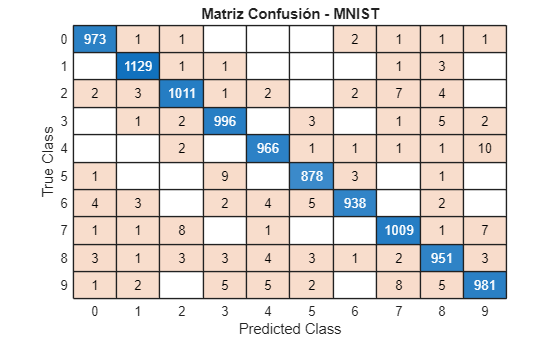

predictedLabelsMNIST = predict(MdlMNIST, testFeaturesMNIST);

% Matriz de confusión y Scores finales
CM_MNIST = confusionmat(labelsTest, predictedLabelsMNIST);
figure; 
confusionchart(labelsTest, predictedLabelsMNIST); 
title('Matriz Confusión - MNIST');


[ClassScoresMNIST, MacroScoresMNIST] = multiclass_scores(CM_MNIST);

% Mostrar tabla final global
GScoresMNIST = array2table(MacroScoresMNIST,'RowNames',{'Global MNIST'},'VariableNames',{'Macro-Recall', 'Macro-Precision','Macro-F1'})

GScoresMNIST = 1×3 table
                    Macro-Recall    Macro-Precision    Macro-F1
                    ____________    _______________    ________

    Global MNIST      0.98306           0.98317        0.98311 


# FUNCIONES

function [ClassScores, GlobalScores] = multiclass_scores(CM)

    % 1. Inicializamos los vectores con ceros (no vacíos)
    num_clases = size(CM, 1);
    Recall = zeros(num_clases, 1);
    Precision = zeros(num_clases, 1);
    F1_Score = zeros(num_clases, 1);

    % 2. Bucle para calcular métricas de cada dígito
    for i = 1 : num_clases
        TP = CM(i,i);                  % Aciertos (Diagonal)
        FN = sum(CM(i,:)) - TP;        % Falsos Negativos (Fila - Aciertos)
        FP = sum(CM(:,i)) - TP;        % Falsos Positivos (Columna - Aciertos)

        % sumamos 'eps' para evitar división por cero si es 0
        Recall(i)    = TP / (TP + FN + eps);
        Precision(i) = TP / (TP + FP + eps);
        F1_Score(i)  = 2 * (Precision(i) * Recall(i)) / (Precision(i) + Recall(i) + eps);
    end

    % 3. Guardamos resultados por clase (Mx3)
    ClassScores = [Recall, Precision, F1_Score];
      
    % 4. Calculamos promedios globales (Macro)
    GlobalScores = [mean(Recall), mean(Precision), mean(F1_Score)];

end
